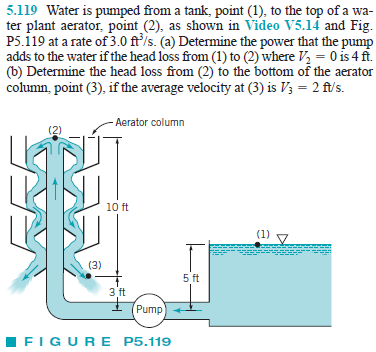

# constants

u = symunit;
gamma = 62.4*u.lbf/u.ft^3;
g = 32.2*u.ft/u.s^2;

# state 1

p1 = 0;
V1 = 0;
z1 = 5*u.ft;

# state 2

p2 = 0;
V2 = 0;
z2 = 13*u.ft;

# state 3

p3 = 0;
V3 = 2*u.ft/u.s;
z3 = 3*u.ft;

# head loss from states 1-2

% --------------
% given
Wdot_12 = sym('Wdot_12');
Q_12 = 3.0*u.ft^3/u.s;
hs_12(Wdot_12) = rewrite(Wdot_12/(gamma*Q_12), [u.HP_UK u.ft]);
hL_12 = 4*u.ft;
% --------------
% conservation of energy
Wdot_12 = solve(p2/gamma+V2^2/(2*g)+z2 == p1/gamma+V1^2/(2*g)+z1+hs_12-hL_12);
Wdot_12 = rewrite(Wdot_12, u.HP_UK);
Wdot_12_vpa = vpa(Wdot_12, 3)

$$Wdot\_12\_vpa = 4.08\,{\mathrm{HP}}_{\mathrm{UK}}$$

% --------------

# head loss from states 2-3

% --------------
% given
hL_23 = sym('hL_23');
% --------------
% conservation of energy
hL_23 = solve(p3/gamma+V3^2/(2*g)+z3 == p2/gamma+V2^2/(2*g)+z2-hL_23);
hL_23_vpa = vpa(hL_23, 3)

$$hL\_23\_vpa = 9.94\,\mathrm{ft}$$

% --------------